Júlia Gasull

# Robot Morphology

Location of RTB robot manipulator models: `.../MatlabDrive/RVC2/rvctools/robot/models`

`Team: Júlia Gasull (no sabía que se podía hacer por parejas)`

`Link: https://drive.matlab.com/sharing/6dcd7b54-2409-4cec-9320-c294080c0e0f`

## 6R Robot. Puma 560

Before start the exercise see the videos: 

- [https://youtu.be/ArzP7rh4_9Q](https://youtu.be/ArzP7rh4_9Q) (shows the robot is a 6R) and

- [https://youtu.be/aHV5oY7viBM](https://youtu.be/aHV5oY7viBM) (the 6R drawing)

### Call the robot object and plot it

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


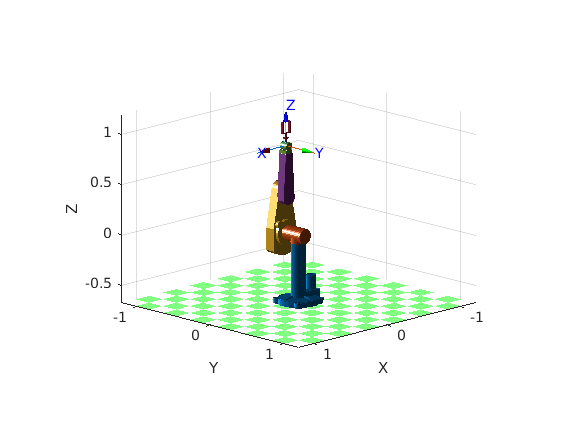

close all
clear
mdl_puma560 % Invoque the puma object
p560.plot3d(qr) % qz is the joint vector 1x6. Try qr, qn, any within the limits

### Work with the wire model and change the point of view. 

See: [https://es.mathworks.com/help/matlab/creating_plots/setting-the-viewpoint-with-azimuth-and-elevation.html](https://es.mathworks.com/help/matlab/creating_plots/setting-the-viewpoint-with-azimuth-and-elevation.html) 

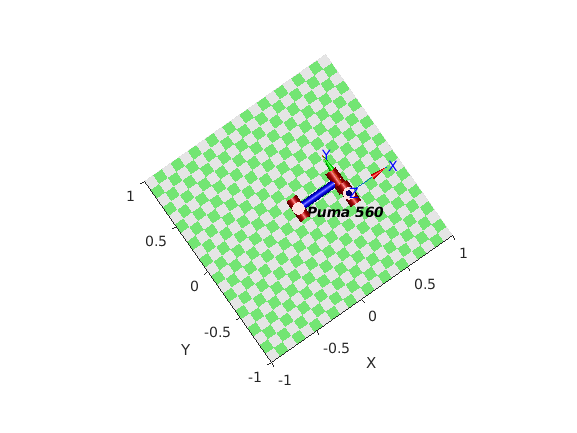

close all
p560.plot(qz)
view([-35 90])

% view([-37.5 30])

### Play with the teach 

It is a kind of Joystick

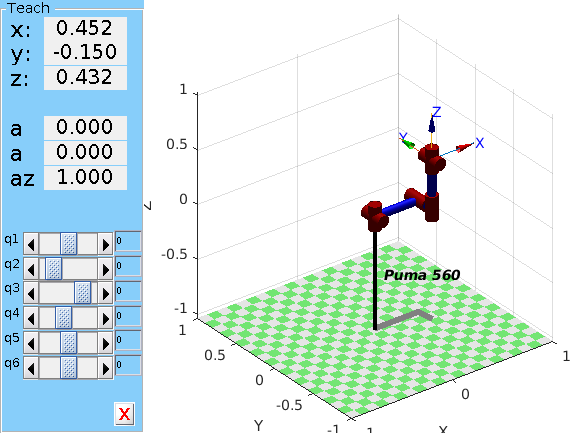

view([-37.5 30])
p560.teach('approach')

### Moving the Robot

clear all
close all
mdl_puma560

Declare a joint motion by adding rows

Q=zeros(100,6); % at the moment no motion

See the Joint 1 limits

q1_limits=p560.links(1, 1).qlim 

q1_limits =    -2.7925    2.7925


Build the joint's motion. Firts only Joint #1

q1=linspace(q1_limits(1),q1_limits(2),100)';
Q=[q1 Q(:,2:6)]

Q =    -2.7925         0         0         0         0         0
   -2.7361         0         0         0         0         0
   -2.6797         0         0         0         0         0
   -2.6233         0         0         0         0         0
   -2.5669         0         0         0         0         0
   -2.5105         0         0         0         0         0
   -2.4540         0         0         0         0         0
   -2.3976         0         0         0         0         0
   -2.3412         0         0         0         0         0
   -2.2848         0         0         0         0         0


Plotting

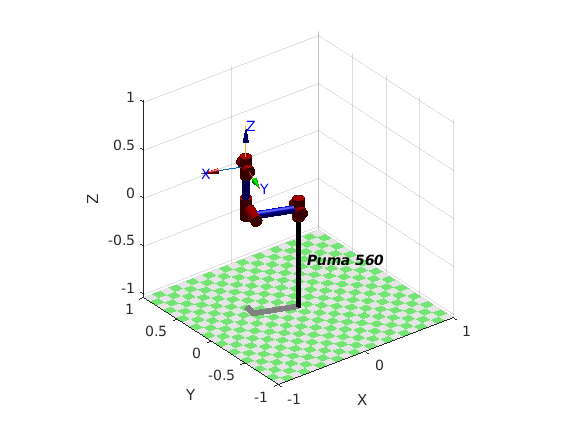

p560.plot(Q)

### Play with the plot options

Moving two joints. See above

q2_limits=p560.links(1, 2).qlim 

q2_limits =    -0.7854    3.9270


q2=linspace(q2_limits(1),q2_limits(2),100)';
Q12=[q1 q2 Q(:,3:6)];

**Options**: Add a trail to see the trajectory, display the join axis, make biger or smaller the robot

Visit the RTB manual.pdf at:

- [https://atenea.upc.edu/pluginfile.php/3871049/mod_resource/content/3/robot.pdf](https://atenea.upc.edu/pluginfile.php/3871049/mod_resource/content/3/robot.pdf) or

- [https://petercorke.com/toolboxes/robotics-toolbox/](https://petercorke.com/toolboxes/robotics-toolbox/) 

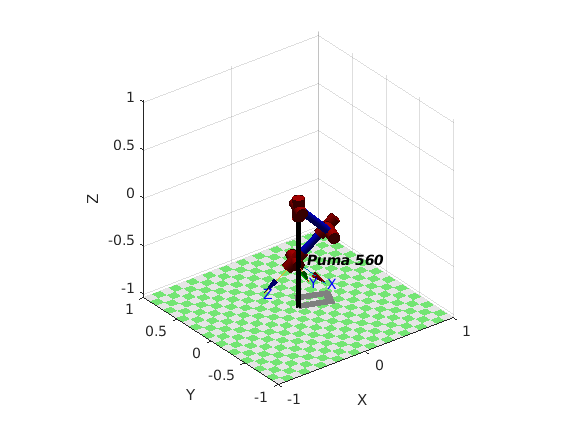

p560.plot(Q12,'trail','--','jaxes','zoom',2) %% Play outside the mlx file to see it: copy the setence in Command Window

Play with other options to get familiar with. You must! becouse all along the course it will be necesary

### Recovering End efector position

Use function 'fkine' for recovering the finger tips of the robot

T=p560.fkine(Q12); % Forward Kinematic to be explained. Given Theta's (q's) obtain the robot EE position
ft=[T.t] % to gert only the position

ft =    -0.6386   -0.6335   -0.6251   -0.6135   -0.5990   -0.5817   -0.5618   -0.5397   -0.5155   -0.4896   -0.4623   -0.4340   -0.4048   -0.3753   -0.3456   -0.3163   -0.2875   -0.2596   -0.2329   -0.2077   -0.1843   -0.1629   -0.1437   -0.1270   -0.1128   -0.1013   -0.0927   -0.0869   -0.0840   -0.0841   -0.0869   -0.0926   -0.1009   -0.1118   -0.1250   -0.1404   -0.1576   -0.1766   -0.1970   -0.2184   -0.2407   -0.2635   -0.2864   -0.3092   -0.3316   -0.3531   -0.3735   -0.3924   -0.4097   -0.4250
   -0.0728   -0.1086   -0.1436   -0.1772   -0.2092   -0.2393   -0.2672   -0.2928   -0.3157   -0.3359   -0.3532   -0.3674   -0.3786   -0.3866   -0.3914   -0.3932   -0.3918   -0.3876   -0.3805   -0.3708   -0.3586   -0.3442   -0.3278   -0.3097   -0.2901   -0.2694   -0.2479   -0.2258   -0.2036   -0.1816   -0.1600   -0.1392   -0.1195   -0.1011   -0.0844   -0.0697   -0.0570   -0.0467   -0.0390   -0.0339   -0.0316   -0.0321   -0.0356   -0.0420   -0.0513   -0.0634   -0.0783   -0.0958   -0.1158   -

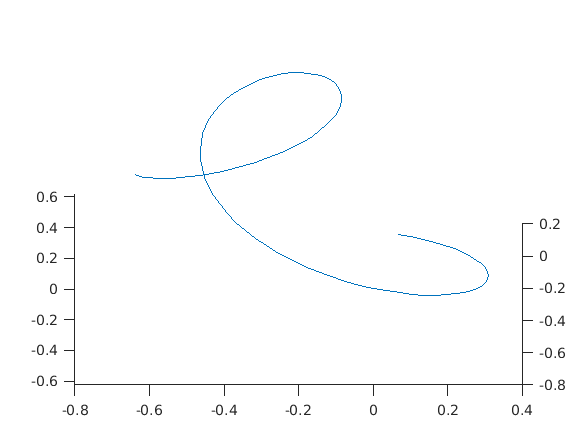

figure
plot3(ft(1,:),ft(2,:), ft(3,:))
view(0,40)

### Working area

clear all
close all
mdl_puma560
q2_limits=p560.links(1, 2).qlim 

q2_limits =    -0.7854    3.9270


q2=linspace(q2_limits(1),q2_limits(2),100)';
Q= [zeros(100,1) linspace(q2_limits(1),q2_limits(2),100)' zeros(100,4) ]

Q =          0   -0.7854         0         0         0         0
         0   -0.7378         0         0         0         0
         0   -0.6902         0         0         0         0
         0   -0.6426         0         0         0         0
         0   -0.5950         0         0         0         0
         0   -0.5474         0         0         0         0
         0   -0.4998         0         0         0         0
         0   -0.4522         0         0         0         0
         0   -0.4046         0         0         0         0
         0   -0.3570         0         0         0         0


p560.plot(Q,'trail','--','jaxes','zoom',2)
T=p560.fkine(Q);
ft=[T.t]

ft =     0.6250    0.6250    0.6235    0.6207    0.6164    0.6108    0.6037    0.5953    0.5856    0.5745    0.5621    0.5485    0.5336    0.5174    0.5002    0.4818    0.4622    0.4417    0.4201    0.3976    0.3742    0.3500    0.3249    0.2992    0.2727    0.2456    0.2180    0.1899    0.1613    0.1324    0.1032    0.0737    0.0441    0.0144   -0.0154   -0.0451   -0.0747   -0.1042   -0.1334   -0.1623   -0.1909   -0.2190   -0.2466   -0.2736   -0.3001   -0.3258   -0.3508   -0.3751   -0.3984   -0.4209
   -0.1501   -0.1501   -0.1501   -0.1501   -0.1501   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -

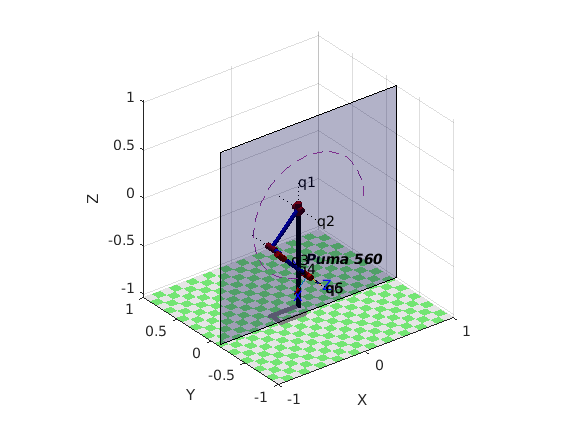

hold on
v = [-1 -0.1501 -1 ; 1 -0.1501 -1 ; 1 -0.1501 1; -1 -0.1501 1];
f = [1 2 3 4];
patch('Faces',f,'Vertices',v,'FaceColor','blue','FaceAlpha',.3)

## IRB140 exercise

Make the same exercise for the irb140 manipulator and plot the working area as shown in the figure

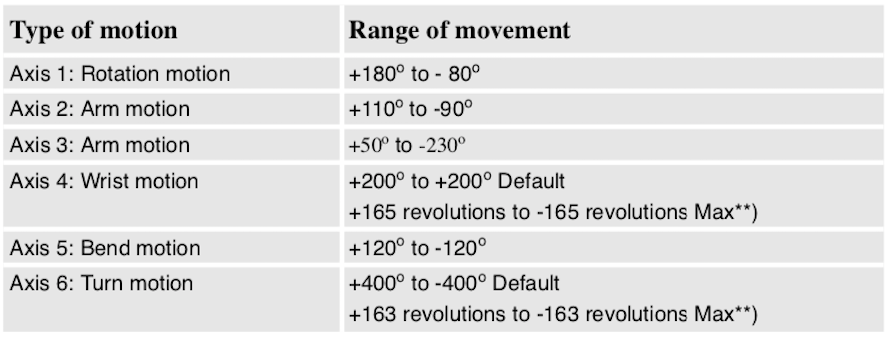

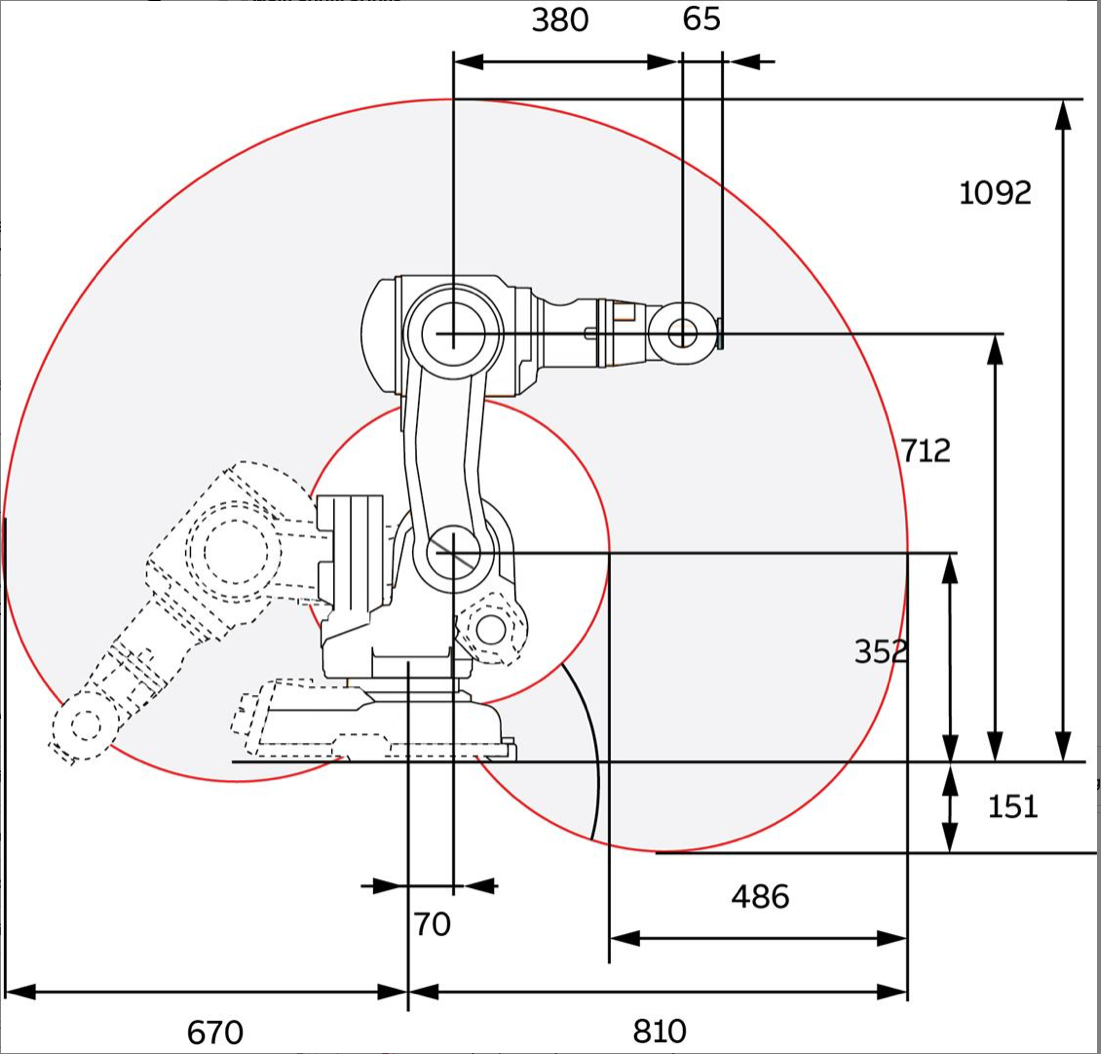

### Invoque IRB140 

clear
close all
mdl_irb140

 
robot = 
 
IRB 140 [ABB]:: 6 axis, RRRRRR, stdDH, slowRNE                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.352|       0.07|    -1.5708|          0|
|  2|         q2|          0|       0.36|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|         q4|       0.38|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


### Plot the IRB

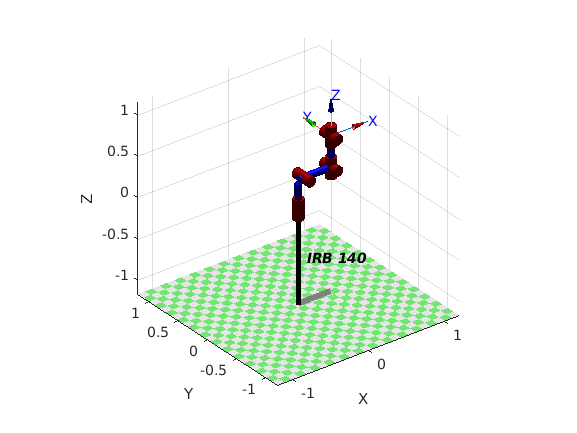

irb140.plot(qz)

Workspace TODO.

- Q1.- Irb140 object has empty the field of q_limints. Use the given table. Remenbe the variables can be written. Translate it to radians.

- Q2. Do not confuse yourselft with 'qz'. It is just a robot configuration. Use 'qr' joint configuration as the home position. (q2 and q3 facing up)

- Q3. From that pose you can add and substract half range.

- Q4. I am going to give you the pseudo code for the outer right positions

-     a) interpolate joint 2 (q2) from qr till (qr+half range), its limit. 

-     b) Then interpolate joint 3 (q3) from qr till (qr+half range), its limit. 

-     c) Build the Q (200x6) matrix of joints space 

-     d) Use 'ikine' function to recover {EE} position.You will get first and fourth quadrant.

The solution I am giving to you do not take into consideration the asimetry in

the ranges. But I hope it will inspire you.

### Working area

clear all
close all

mdl_irb140

 
robot = 
 
IRB 140 [ABB]:: 6 axis, RRRRRR, stdDH, slowRNE                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.352|       0.07|    -1.5708|          0|
|  2|         q2|          0|       0.36|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|         q4|       0.38|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



limits = [-80 180; -90 110; -230 50] 

limits =    -80   180
   -90   110
  -230    50


limits = deg2rad(limits)

limits =    -1.3963    3.1416
   -1.5708    1.9199
   -4.0143    0.8727



irb140.links(2).qlim = limits(2,:)

 
irb140 = 
 
IRB 140 [ABB]:: 6 axis, RRRRRR, stdDH, slowRNE                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.352|       0.07|    -1.5708|          0|
|  2|         q2|          0|       0.36|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|         q4|       0.38|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


irb140.links(3).qlim = limits(3,:)

 
irb140 = 
 
IRB 140 [ABB]:: 6 axis, RRRRRR, stdDH, slowRNE                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.352|       0.07|    -1.5708|          0|
|  2|         q2|          0|       0.36|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|         q4|       0.38|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



position0 = [qr(1) qr(2)+limits(2,1) qr(3)+limits(3,1) qr(4:6)];
irb140.plot(position0)
view(0,0)

index = 200;
q1 = zeros(index,1) + qr(1);
q2 = linspace(qr(2)+limits(2,1),limits(2,2),index)';
q3 = linspace(qr(3)+limits(3,1),limits(3,2),index)';
q4_6 = zeros(index,3) + qr(4:6);
Q = [q1 q2 q3 q4_6]

Q =          0   -3.1416   -2.4435         0    1.5708   -1.5708
         0   -3.1162   -2.4268         0    1.5708   -1.5708
         0   -3.0907   -2.4101         0    1.5708   -1.5708
         0   -3.0653   -2.3935         0    1.5708   -1.5708
         0   -3.0399   -2.3768         0    1.5708   -1.5708
         0   -3.0144   -2.3601         0    1.5708   -1.5708
         0   -2.9890   -2.3435         0    1.5708   -1.5708
         0   -2.9636   -2.3268         0    1.5708   -1.5708
         0   -2.9381   -2.3101         0    1.5708   -1.5708
         0   -2.9127   -2.2935         0    1.5708   -1.5708




irb140.plot(Q,'trail','--','jaxes','zoom',2)

T = irb140.fkine(Q); ft = [T.t]

ft =    -0.0457   -0.0336   -0.0217   -0.0100    0.0015    0.0126    0.0234    0.0340    0.0442    0.0540    0.0635    0.0726    0.0813    0.0896    0.0974    0.1049    0.1119    0.1185    0.1246    0.1302    0.1354    0.1401    0.1444    0.1481    0.1514    0.1542    0.1566    0.1584    0.1598    0.1608    0.1612    0.1613    0.1608    0.1600    0.1586    0.1569    0.1548    0.1523    0.1494    0.1461    0.1424    0.1385    0.1342    0.1295    0.1246    0.1195    0.1140    0.1084    0.1025    0.0964
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

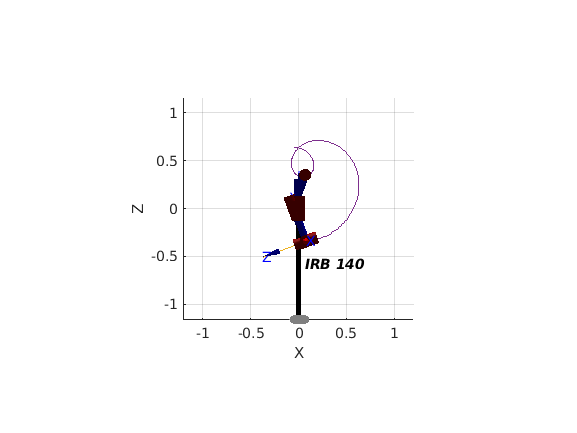

hold on
plot3(ft(1,:),ft(2,:), ft(3,:))